# **LAB**

## LAB: Bearing Fault Diagnosis

**Name: Hong Se Hyun (21700791)**

**Instruction**

Read the reference journal and implement in MATLAB

- Thomas W. Rauber et al. "Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis", IEEE TRANSACTIONS ON INDUSTRIAL ELECTRONICS, VOL. 62, NO. 1, JANUARY 2015

#### Dataset

- CWRU dataset similarly to Journal dataset

- Download CWRU dataset for this journal: [Download here](https://drive.google.com/file/d/1pv-0E8hA77Nr5-gHwVgPq3PR2rdyCj_-/view?usp=sharing)

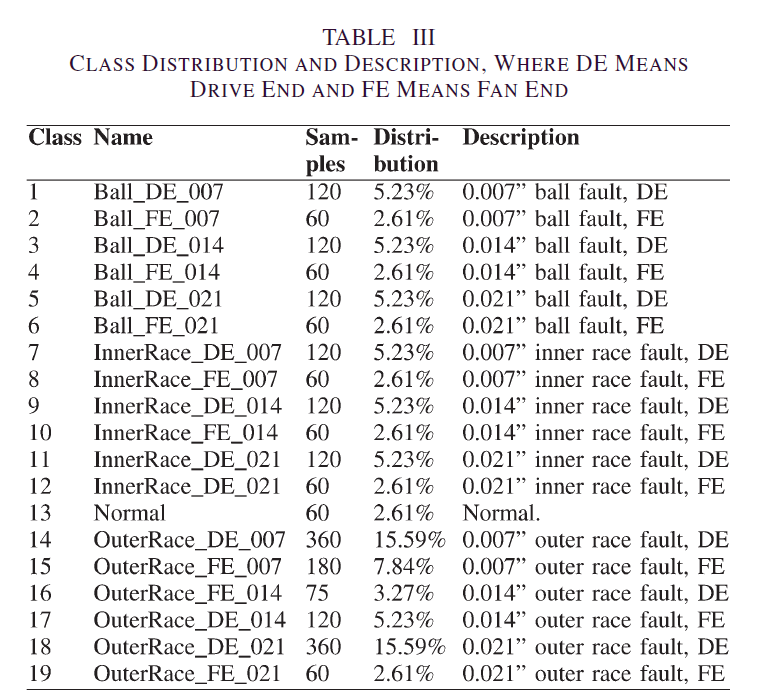

Sampling: 

- **Drive end bearing(12K): 12,000 samples/second**

Classes:

- Normal / Outer Race fault / Inner Race fault / Ball Fault

- fault diameter of 0.007inches

- fault diameter of 0.014inches

- fault diameter of 0.021inches

Variables

- DE - drive end accelerometer data             drive end bearing

- FE - fan end accelerometer data                fan end bearing

- BA - base accelerometer data                    base bearing

- time - time series data

- RPM - shaft rpm during testing

### Drive End Bearing Experiment- 12K

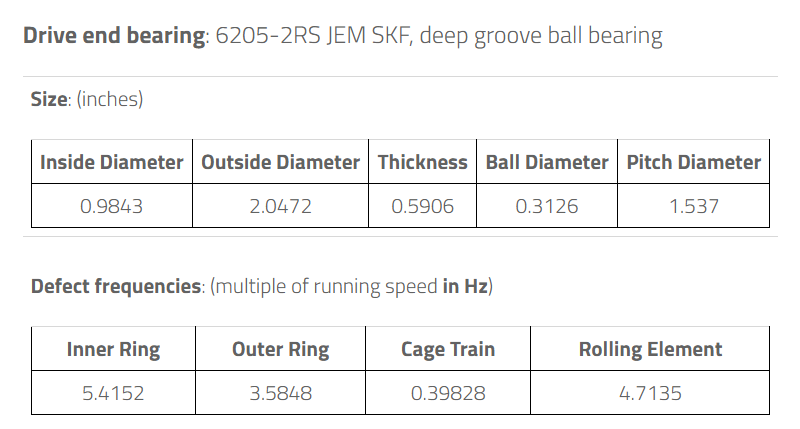

**For Feature Extraction**

- Statistical Features

- Complex Envelope Analysis

- Wavelet Package Analysis

**For Feature Reduction/Selection Use only**

- Sequential Forward Selection

- PCA

**For Classification Use**

- SVM

- KNN

- Decision Tree

*Experiment* Output: Accuracy & Confusion Matrix

**EX1. Without Selection**

- Features:Statistical / Envelope / WPT / Global Pool

- Classifer: SVM / K-NN / Decision Tree

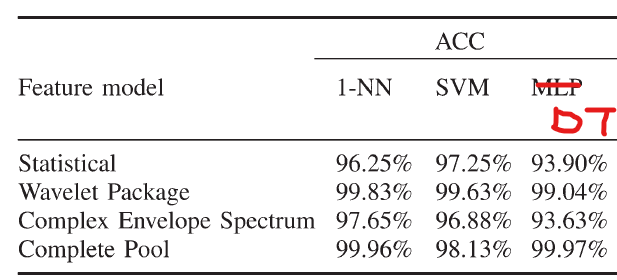

**EX2. With Selection/Reduction**

- Features: Global Pool

- Selection: PCA / Forward selection

- Classifer: SVM / K-NN / Decision Tree

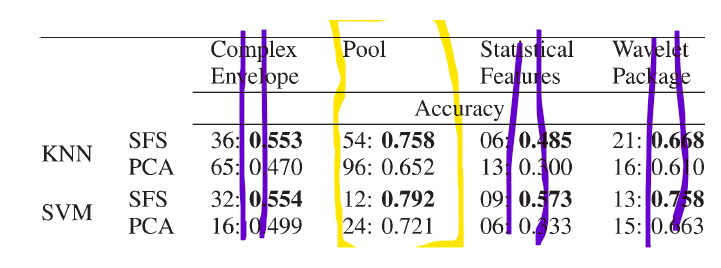

# **1. Data Pre-processing**

### **1-1. Load Data**

close all
clear
clc

% -------- Load Ball Data [DE] ---------- %
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Ball_DE_0007.mat');  % X118
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Ball_DE_0014.mat');  % X185
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Ball_DE_0021.mat');  % X222
% -------- Load Ball Data [FE] ---------- %
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Ball_FE_0007.mat');  % X282
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Ball_FE_0014.mat');  % X286
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Ball_FE_0021.mat');  % X290

% -------- Load Inner Data [DE] ---------- %
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\IR_DE_0007.mat');    % X105
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\IR_DE_0014.mat');    % X169
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\IR_DE_0021.mat');    % X209
% -------- Load Inner Data [FE] ---------- %
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\IR_FE_0007.mat');    % X278
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\IR_FE_0014.mat');    % X274
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\IR_FE_0021.mat');    % X270

% -------- Load Outer Data [DE] ---------- %
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\OR_DE_0007.mat');    % X130
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\OR_DE_0014.mat');    % X197
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\OR_DE_0021.mat');    % X234
% -------- Load Outer Data [FE] ---------- %
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\OR_FE_0007.mat');    % X294
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\OR_FE_0014.mat');    % X313
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\OR_FE_0021.mat');    % X315

% ---------- Load Normal Data ------------ %
load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Normal_1.mat');      % X097
%load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Normal_2.mat');      % X098
%load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Normal_3.mat');      % X099
%load('C:\Users\sehye\source\repos\DTA_2022\DTA_matlab\Lab\CWRU_Data_Journal\Normal_4.mat');      % X100

### 1-2. Initial Value Setting

N     = 120000;          % -------- Number   of   Data ---------- %
Dv    = 15;              % -------- Division  Criteria ---------- %
Fs    = 12000;           % ---- RPM   [Sampling  Frequency] ----- %

% ---------- Fault  Frequency ---------- %
% ---------- Defect Frequency ---------- %
% DE :: Inner Ring             = 5.4152  %
% DE :: Outer Ring             = 3.5848  %
% DE :: Cage Train             = 0.39828 %
% DE :: Rolling Element        = 4.7135  %
DE_BPFI = 5.4152*(1800/60);    % Fault Frequency of Inner   // Let's say the rpm is 1800 based on Journal.
DE_BPFO = 3.5848*(1800/60);    % Fault Frequency of Outer   // Let's say the rpm is 1800.
DE_BSF  = 4.7135*(1800/60);    % Fault Frequency of Ball    // Let's say the rpm is 1800.

% FE :: Inner Ring             = 4.9469  %
% FE :: Outer Ring             = 3.0530  %
% FE :: Cage Train             = 0.3817  %
% FE :: Rolling Element        = 3.9874  %
FE_BPFI = 4.9469*(1800/60);    % Fault Frequency of Inner   // Let's say the rpm is 1800.
FE_BPFO = 3.0530*(1800/60);    % Fault Frequency of Outer   // Let's say the rpm is 1800.
FE_BSF  = 3.9874*(1800/60);    % Fault Frequency of Ball    // Let's say the rpm is 1800.

# **2. Feature Extraction**

### **2-1. Time Features & Frequency Features [26 statistical features]**

% ---------  Ball Data Time-Frequency Feature Table  ----------- %
T1_Ball_0007           = Time_Freq_FeatureTable(X118_DE_time,X282_FE_time,N,Dv,"Ball_0007");
T2_Ball_0014           = Time_Freq_FeatureTable(X185_DE_time,X286_FE_time,N,Dv,"Ball_0014");
T3_Ball_0021           = Time_Freq_FeatureTable(X222_DE_time,X290_FE_time,N,Dv,"Ball_0021");
TimeFreq_Table_Ball    = [T1_Ball_0007 ; T2_Ball_0014 ; T3_Ball_0021];

% --------- Inner Data Time-Frequency Feature Table ------------ %
T4_Inner_0007          = Time_Freq_FeatureTable(X105_DE_time,X278_FE_time,N,Dv,"Inner_0007");
T5_Inner_0014          = Time_Freq_FeatureTable(X169_DE_time,X274_FE_time,N,Dv,"Inner_0014");
T6_Inner_0021          = Time_Freq_FeatureTable(X209_DE_time,X270_FE_time,N,Dv,"Inner_0021");
TimeFreq_Table_Inner   = [T4_Inner_0007 ; T5_Inner_0014 ; T6_Inner_0021];

% --------- Outer Data Time-Frequency Feature Table ------------ %
T7_Outer_0007          = Time_Freq_FeatureTable(X130_DE_time,X294_FE_time,N,Dv,"Outer_0007");
T8_Outer_0014          = Time_Freq_FeatureTable(X197_DE_time,X313_FE_time,N,Dv,"Outer_0014");
T9_Outer_0021          = Time_Freq_FeatureTable(X234_DE_time,X315_FE_time,N,Dv,"Outer_0021");
TimeFreq_Table_Outer   = [T7_Outer_0007 ; T8_Outer_0014 ; T9_Outer_0021];

% --------- Normal Data Time-Frequency Feature Table ----------- %
T10_Normal_1           = Time_Freq_FeatureTable(X097_DE_time,X097_FE_time,N,Dv,"Normal_1");
%T11_Normal_2          = Time_Freq_FeatureTable(X098_DE_time,X098_FE_time,N,Dv,"Normal_2");
%T12_Normal_3          = Time_Freq_FeatureTable(X099_DE_time,X099_FE_time,N,Dv,"Normal_3");
%T13_Normal_4          = Time_Freq_FeatureTable(X100_DE_time,X100_FE_time,N,Dv,"Normal_4");
%TimeFreq_Table_Normal = [T10_Normal_1 ; T11_Normal_2 ; T12_Normal_3 ; T13_Normal_4];
TimeFreq_Table_Normal  = T10_Normal_1;


% ------------------- Generate Full Table --------------------- %
% ------------------- Generate Full Table --------------------- %
TimeFreq_Table         = [TimeFreq_Table_Ball ; TimeFreq_Table_Inner ; TimeFreq_Table_Outer ; TimeFreq_Table_Normal];
TimeFreq_Class         = get_Class_method_1(TimeFreq_Table);
TimeFreq_Table_Class   = [TimeFreq_Table TimeFreq_Class];

TimeFreq_Table_Class.Properties.VariableNames{'Var27'} = 'Class'

TimeFreq_Table_Class = 150×27 table
                    DE_rms      DE_sra     DE_kv       DE_sk       DE_ppv     DE_cf     DE_if     DE_mf     DE_sf     DE_kf       DE_fc       DE_rmsf      DE_rvf      FE_rms      FE_sra     FE_kv       FE_sk      FE_ppv    FE_cf     FE_if     FE_mf     FE_sf     FE_kf       FE_fc       FE_rmsf      FE_rvf          Class    
                    _______    ________    ______    __________    _______    ______    ______    ______    ______    ______    _________    _________    _________    _______    ________    ______    _________    ______    ______    ______    ______    ______    ______    _________    _________    _________    _____________

    Ball_0007_1     0.13699    0.093363    2.9497     -0.017602     1.0295    3.7991    4.7406    5.5744    1.2478    8375.5    0.0013398    0.0030532    0.0019402    0.18101    0.098149    11.389     0.036041    2.9874    8.7087    12.794    16.061    1.4692     10609    0.0019803    0.0040403    0.0024906   

### **2-2. Envelope Features [72 complex envelope features]**

% ---------  Ball Data Envelope Features Table  ----------- %
T1_Ball_0007           = Envelope_FeatureTable(X118_DE_time,X118_FE_time,X282_DE_time,X282_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Ball_0007");
T2_Ball_0014           = Envelope_FeatureTable(X185_DE_time,X185_FE_time,X286_DE_time,X286_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Ball_0014");
T3_Ball_0021           = Envelope_FeatureTable(X222_DE_time,X222_FE_time,X290_DE_time,X290_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Ball_0021");
Envelope_Table_Ball    = [T1_Ball_0007 ; T2_Ball_0014 ; T3_Ball_0021];

% ---------  Inner Data Envelope Features Table  ----------- %
T4_Inner_0007          = Envelope_FeatureTable(X105_DE_time,X105_FE_time,X278_DE_time,X278_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Inner_0007");
T5_Inner_0014          = Envelope_FeatureTable(X169_DE_time,X169_FE_time,X274_DE_time,X274_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Inner_0014");
T6_Inner_0021          = Envelope_FeatureTable(X209_DE_time,X209_FE_time,X270_DE_time,X270_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Inner_0021");
Envelope_Table_Inner   = [T4_Inner_0007 ; T5_Inner_0014 ; T6_Inner_0021];

% ---------  Outer Data Envelope Features Table  ----------- %
T7_Outer_0007          = Envelope_FeatureTable(X130_DE_time,X130_FE_time,X294_DE_time,X294_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Outer_0007");
T8_Outer_0014          = Envelope_FeatureTable(X197_DE_time,X197_FE_time,X313_DE_time,X313_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Outer_0014");
T9_Outer_0021          = Envelope_FeatureTable(X234_DE_time,X234_FE_time,X315_DE_time,X315_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Outer_0021");
Envelope_Table_Outer   = [T7_Outer_0007 ; T8_Outer_0014 ; T9_Outer_0021];

% ---------  Normal Data Envelope Features Table  ----------- %
T10_Normal_1           = Envelope_FeatureTable(X097_DE_time,X097_FE_time,X097_DE_time,X097_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Normal_1");
%T11_Normal_2          = Envelope_FeatureTable(X098_DE_time,X098_FE_time,X098_DE_time,X098_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Normal_2");%
%T12_Normal_3          = Envelope_FeatureTable(X099_DE_time,X099_FE_time,X099_DE_time,X099_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Normal_3");
%T13_Normal_4          = Envelope_FeatureTable(X100_DE_time,X100_FE_time,X100_DE_time,X100_FE_time,N,Dv,Fs,DE_BPFI,DE_BPFO,DE_BSF,FE_BPFI,FE_BPFO,FE_BSF,"Normal_4");
%Envelope_Table_Normal = [T10_Normal_1 ; T11_Normal_2 ; T12_Normal_3 ; T13_Normal_4];
Envelope_Table_Normal  = T10_Normal_1;


% ------------------- Generate Full Table --------------------- %
% ------------------- Generate Full Table --------------------- %
Envelope_Table         = [Envelope_Table_Ball ; Envelope_Table_Inner ; Envelope_Table_Outer ; Envelope_Table_Normal];
Envelope_Class         = get_Class_method_1(Envelope_Table);
Envelope_Table_Class   = [Envelope_Table Envelope_Class];

Envelope_Table_Class.Properties.VariableNames{'Var73'} = 'Class'

Envelope_Table_Class = 150×73 table
                    Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPFI_Harmonic_5    Env_DEFE_BPFI_Harmonic_6    Env_DEFE_BPFO_Harmonic_1    Env_DEFE_BPFO_Harmonic_2    Env_DEFE_BPFO_Harmonic_3    Env_DEFE_BPFO_Harmonic_4    Env_DEFE_BPFO_Harmonic_5    Env_DEFE_BPFO_Harmonic_6    Env_DEFE_BSF_Harmonic_1    Env_DEFE_BSF_Harmonic_2    Env_DEFE_BSF_Harmonic_3    Env_DEFE_BSF_Harmonic_4    En

### **2-3. Wavelet Features [32 wavelet package features]**

% ---------  Ball Data Time-Frequency Feature Table  ----------- %
T1_Ball_0007           = Wavelet_Packet_FeatureTable(X118_DE_time,X282_FE_time,N,Dv,4,"db4","Ball_0007");
T2_Ball_0014           = Wavelet_Packet_FeatureTable(X185_DE_time,X286_FE_time,N,Dv,4,"db4","Ball_0014");
T3_Ball_0021           = Wavelet_Packet_FeatureTable(X222_DE_time,X290_FE_time,N,Dv,4,"db4","Ball_0021");
Wavelet_Table_Ball     = [T1_Ball_0007 ; T2_Ball_0014 ; T3_Ball_0021];

% --------- Inner Data Time-Frequency Feature Table ------------ %
T4_Inner_0007          = Wavelet_Packet_FeatureTable(X105_DE_time,X278_FE_time,N,Dv,4,"db4","Inner_0007");
T5_Inner_0014          = Wavelet_Packet_FeatureTable(X169_DE_time,X274_FE_time,N,Dv,4,"db4","Inner_0014");
T6_Inner_0021          = Wavelet_Packet_FeatureTable(X209_DE_time,X270_FE_time,N,Dv,4,"db4","Inner_0021");
Wavelet_Table_Inner    = [T4_Inner_0007 ; T5_Inner_0014 ; T6_Inner_0021];

% --------- Outer Data Time-Frequency Feature Table ------------ %
T7_Outer_0007          = Wavelet_Packet_FeatureTable(X130_DE_time,X294_FE_time,N,Dv,4,"db4","Outer_0007");
T8_Outer_0014          = Wavelet_Packet_FeatureTable(X197_DE_time,X313_FE_time,N,Dv,4,"db4","Outer_0014");
T9_Outer_0021          = Wavelet_Packet_FeatureTable(X234_DE_time,X315_FE_time,N,Dv,4,"db4","Outer_0021");
Wavelet_Table_Outer    = [T7_Outer_0007 ; T8_Outer_0014 ; T9_Outer_0021];

% --------- Normal Data Time-Frequency Feature Table ----------- %
T10_Normal_1           = Wavelet_Packet_FeatureTable(X097_DE_time,X097_FE_time,N,Dv,4,"db4","Normal_1");
%T11_Normal_2          = Wavelet_Packet_FeatureTable(X098_DE_time,X098_FE_time,N,Dv,4,"db4","Normal_2");
%T12_Normal_3          = Wavelet_Packet_FeatureTable(X099_DE_time,X099_FE_time,N,Dv,4,"db4","Normal_3");
%T13_Normal_4          = Wavelet_Packet_FeatureTable(X100_DE_time,X100_FE_time,N,Dv,4,"db4","Normal_4");
%Wavelet_Table_Normal  = [T10_Normal_1 ; T11_Normal_2 ; T12_Normal_3 ; T13_Normal_4];
Wavelet_Table_Normal   = T10_Normal_1;


% ------------------- Generate Full Table --------------------- %
% ------------------- Generate Full Table --------------------- %
Wavelet_Table         = [Wavelet_Table_Ball ; Wavelet_Table_Inner ; Wavelet_Table_Outer ; Wavelet_Table_Normal];
Wavelet_Class         = get_Class_method_1(Wavelet_Table);
Wavelet_Table_Class   = [Wavelet_Table Wavelet_Class];

Wavelet_Table_Class.Properties.VariableNames{'Var33'} = 'Class'

Wavelet_Table_Class = 150×33 table
                    Energy_DE1    Energy_DE2    Energy_DE3    Energy_DE4    Energy_DE5    Energy_DE6    Energy_DE7    Energy_DE8    Energy_DE9    Energy_DE10    Energy_DE11    Energy_DE12    Energy_DE13    Energy_DE14    Energy_DE15    Energy_DE16    Energy_FE1    Energy_FE2    Energy_FE3    Energy_FE4    Energy_FE5    Energy_FE6    Energy_FE7    Energy_FE8    Energy_FE9    Energy_FE10    Energy_FE11    Energy_FE12    Energy_FE13    Energy_FE14    Energy_FE15    Energy_FE16        Class    
                    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________    __

### **2-4. Generate Global Pool [Total 130 Features]**

Global_Pool_Table         = [TimeFreq_Table, Envelope_Table, Wavelet_Table];
Global_Pool_Class         = get_Class_method_1(Global_Pool_Table);
Global_Pool_Table_Class   = [Global_Pool_Table, Global_Pool_Class];

Global_Pool_Table_Class.Properties.VariableNames{'Var131'} = 'Class'

Global_Pool_Table_Class = 150×131 table
                    DE_rms      DE_sra     DE_kv       DE_sk       DE_ppv     DE_cf     DE_if     DE_mf     DE_sf     DE_kf       DE_fc       DE_rmsf      DE_rvf      FE_rms      FE_sra     FE_kv       FE_sk      FE_ppv    FE_cf     FE_if     FE_mf     FE_sf     FE_kf       FE_fc       FE_rmsf      FE_rvf      Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPFI_Harmonic_5    Env_DEFE_B

# **3. Data Pre-Processing**

### Data Normalizing

TimeFreq_Table_normalized          = normalize(TimeFreq_Table, 'range');
TimeFreq_Table_Class_normalized    = [TimeFreq_Table_normalized TimeFreq_Class];
TimeFreq_Table_Class_normalized.Properties.VariableNames{'Var27'} = 'Class'

TimeFreq_Table_Class_normalized = 150×27 table
                    DE_rms     DE_sra       DE_kv       DE_sk      DE_ppv      DE_cf        DE_if        DE_mf       DE_sf       DE_kf       DE_fc     DE_rmsf     DE_rvf      FE_rms      FE_sra      FE_kv       FE_sk       FE_ppv      FE_cf      FE_if      FE_mf      FE_sf       FE_kf       FE_fc      FE_rmsf      FE_rvf         Class    
                    _______    _______    _________    _______    ________    ________    _________    _________    ________    ________    _______    _______    ________    ________    ________    ________    ________    ________    _______    _______    _______    ________    ________    ________    ________    ________    _____________

    Ball_0007_1     0.10577     0.1781    0.0066386      0.196    0.047381    0.040928     0.033618     0.032003    0.018535    0.040147    0.13597    0.10587    0.094881     0.11251    0.093182     0.19779     0.21566     0.25019    0.43288    0.45919    0.48528     0.

Envelope_Table_normalized          = normalize(Envelope_Table, 'range');
Envelope_Table_Class_normalized    = [Envelope_Table_normalized Envelope_Class];
Envelope_Table_Class_normalized.Properties.VariableNames{'Var73'} = 'Class'

Envelope_Table_Class_normalized = 150×73 table
                    Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPFI_Harmonic_5    Env_DEFE_BPFI_Harmonic_6    Env_DEFE_BPFO_Harmonic_1    Env_DEFE_BPFO_Harmonic_2    Env_DEFE_BPFO_Harmonic_3    Env_DEFE_BPFO_Harmonic_4    Env_DEFE_BPFO_Harmonic_5    Env_DEFE_BPFO_Harmonic_6    Env_DEFE_BSF_Harmonic_1    Env_DEFE_BSF_Harmonic_2    Env_DEFE_BSF_Harmonic_3    Env_DEFE_BSF_Harmo

Wavelet_Table_normalized           = normalize(Wavelet_Table, 'range');
Wavelet_Table_Class_normalized     = [Wavelet_Table_normalized Wavelet_Class];
Wavelet_Table_Class_normalized.Properties.VariableNames{'Var33'} = 'Class'

Wavelet_Table_Class_normalized = 150×33 table
                    Energy_DE1    Energy_DE2    Energy_DE3    Energy_DE4    Energy_DE5    Energy_DE6    Energy_DE7    Energy_DE8    Energy_DE9    Energy_DE10    Energy_DE11    Energy_DE12    Energy_DE13    Energy_DE14    Energy_DE15    Energy_DE16    Energy_FE1    Energy_FE2    Energy_FE3    Energy_FE4    Energy_FE5    Energy_FE6    Energy_FE7    Energy_FE8    Energy_FE9    Energy_FE10    Energy_FE11    Energy_FE12    Energy_FE13    Energy_FE14    Energy_FE15    Energy_FE16        Class    
                    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ______

Global_Pool_Table_normalized       = normalize(Global_Pool_Table, 'range');
Global_Pool_Table_Class_normalized = [Global_Pool_Table_normalized Global_Pool_Class];
Global_Pool_Table_Class_normalized.Properties.VariableNames{'Var131'} = 'Class'

Global_Pool_Table_Class_normalized = 150×131 table
                    DE_rms     DE_sra       DE_kv       DE_sk      DE_ppv      DE_cf        DE_if        DE_mf       DE_sf       DE_kf       DE_fc     DE_rmsf     DE_rvf      FE_rms      FE_sra      FE_kv       FE_sk       FE_ppv      FE_cf      FE_if      FE_mf      FE_sf       FE_kf       FE_fc      FE_rmsf      FE_rvf     Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPF

### Divide TrainData and TestData   [ TrainData 70%,   TestData 30% ]

[TimeFreq_X_trainData, TimeFreq_Y_trainData, TimeFreq_X_testData, TimeFreq_Y_testData] = Divide_Train_Test(TimeFreq_Table_Class_normalized, 0.3)

TimeFreq_X_trainData = 105×26 table
                     DE_rms      DE_sra       DE_kv       DE_sk      DE_ppv      DE_cf        DE_if        DE_mf       DE_sf       DE_kf       DE_fc      DE_rmsf      DE_rvf      FE_rms      FE_sra      FE_kv       FE_sk       FE_ppv      FE_cf      FE_if      FE_mf      FE_sf       FE_kf       FE_fc      FE_rmsf      FE_rvf 
                    ________    ________    _________    _______    ________    ________    _________    _________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    _______    _______    _______    ________    ________    ________    ________    ________

    Ball_0007_2      0.11122     0.18451    0.0069346    0.17181    0.048112    0.037282     0.031593     0.030746    0.024637     0.03655     0.14068     0.11136     0.10027    0.059122    0.061688    0.098397      0.1003     0.17327    0.39954    0.36684    0.36687      0.1796     0.25768     0.11277    

TimeFreq_Y_trainData = 105×1 table
                        Class    
                    _____________

    Ball_0007_2     {'Ball_0007'}
    Ball_0007_3     {'Ball_0007'}
    Ball_0007_4     {'Ball_0007'}
    Ball_0007_5     {'Ball_0007'}
    Ball_0007_6     {'Ball_0007'}
    Ball_0007_7     {'Ball_0007'}
    Ball_0007_8     {'Ball_0007'}
    Ball_0007_13    {'Ball_0007'}
    Ball_0007_14    {'Ball_0007'}
    Ball_0014_1     {'Ball_0014'}
    Ball_0014_3     {'Ball_0014'}
    Ball_0014_4     {'Ball_0014'}
    Ball_0014_6     {'Ball_0014'}
    Ball_0014_7     {'Ball_0014'}
    Ball_0014_10    {'Ball_0014'}
    Ball_0014_12    {'Ball_0014'}


TimeFreq_X_testData = 45×26 table
                     DE_rms      DE_sra       DE_kv       DE_sk      DE_ppv      DE_cf       DE_if       DE_mf       DE_sf       DE_kf       DE_fc      DE_rmsf      DE_rvf      FE_rms      FE_sra      FE_kv       FE_sk       FE_ppv      FE_cf      FE_if      FE_mf      FE_sf       FE_kf       FE_fc      FE_rmsf      FE_rvf 
                    ________    ________    _________    _______    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    _______    _______    _______    ________    ________    ________    ________    ________

    Ball_0007_1      0.10577      0.1781    0.0066386      0.196    0.047381    0.040928    0.033618    0.032003    0.018535    0.040147     0.13597     0.10587    0.094881     0.11251    0.093182     0.19779     0.21566     0.25019    0.43288    0.45919    0.48528     0.45946     0.12549      0.1668     0.11755

TimeFreq_Y_testData = 45×1 table
                        Class    
                    _____________

    Ball_0007_1     {'Ball_0007'}
    Ball_0007_9     {'Ball_0007'}
    Ball_0007_10    {'Ball_0007'}
    Ball_0007_11    {'Ball_0007'}
    Ball_0007_12    {'Ball_0007'}
    Ball_0007_15    {'Ball_0007'}
    Ball_0014_2     {'Ball_0014'}
    Ball_0014_5     {'Ball_0014'}
    Ball_0014_8     {'Ball_0014'}
    Ball_0014_9     {'Ball_0014'}
    Ball_0014_11    {'Ball_0014'}
    Ball_0021_2     {'Ball_0021'}
    Ball_0021_3     {'Ball_0021'}
    Ball_0021_7     {'Ball_0021'}
    Ball_0021_8     {'Ball_0021'}
    Ball_0021_9     {'Ball_0021'}


[Envelope_X_trainData, Envelope_Y_trainData, Envelope_X_testData, Envelope_Y_testData] = Divide_Train_Test(Envelope_Table_Class_normalized, 0.3)

Envelope_X_trainData = 105×72 table
                    Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPFI_Harmonic_5    Env_DEFE_BPFI_Harmonic_6    Env_DEFE_BPFO_Harmonic_1    Env_DEFE_BPFO_Harmonic_2    Env_DEFE_BPFO_Harmonic_3    Env_DEFE_BPFO_Harmonic_4    Env_DEFE_BPFO_Harmonic_5    Env_DEFE_BPFO_Harmonic_6    Env_DEFE_BSF_Harmonic_1    Env_DEFE_BSF_Harmonic_2    Env_DEFE_BSF_Harmonic_3    Env_DEFE_BSF_Harmonic_4    En

Envelope_Y_trainData = 105×1 table
                        Class    
                    _____________

    Ball_0007_1     {'Ball_0007'}
    Ball_0007_3     {'Ball_0007'}
    Ball_0007_6     {'Ball_0007'}
    Ball_0007_7     {'Ball_0007'}
    Ball_0007_8     {'Ball_0007'}
    Ball_0007_9     {'Ball_0007'}
    Ball_0007_10    {'Ball_0007'}
    Ball_0007_11    {'Ball_0007'}
    Ball_0007_14    {'Ball_0007'}
    Ball_0007_15    {'Ball_0007'}
    Ball_0014_1     {'Ball_0014'}
    Ball_0014_2     {'Ball_0014'}
    Ball_0014_5     {'Ball_0014'}
    Ball_0014_6     {'Ball_0014'}
    Ball_0014_8     {'Ball_0014'}
    Ball_0014_9     {'Ball_0014'}


Envelope_X_testData = 45×72 table
                     Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPFI_Harmonic_5    Env_DEFE_BPFI_Harmonic_6    Env_DEFE_BPFO_Harmonic_1    Env_DEFE_BPFO_Harmonic_2    Env_DEFE_BPFO_Harmonic_3    Env_DEFE_BPFO_Harmonic_4    Env_DEFE_BPFO_Harmonic_5    Env_DEFE_BPFO_Harmonic_6    Env_DEFE_BSF_Harmonic_1    Env_DEFE_BSF_Harmonic_2    Env_DEFE_BSF_Harmonic_3    Env_DEFE_BSF_Harmonic_4    Env

Envelope_Y_testData = 45×1 table
                         Class     
                     ______________

    Ball_0007_2      {'Ball_0007' }
    Ball_0007_4      {'Ball_0007' }
    Ball_0007_5      {'Ball_0007' }
    Ball_0007_12     {'Ball_0007' }
    Ball_0007_13     {'Ball_0007' }
    Ball_0014_3      {'Ball_0014' }
    Ball_0014_4      {'Ball_0014' }
    Ball_0014_7      {'Ball_0014' }
    Ball_0014_12     {'Ball_0014' }
    Ball_0021_6      {'Ball_0021' }
    Ball_0021_9      {'Ball_0021' }
    Inner_0007_3     {'Inner_0007'}
    Inner_0007_4     {'Inner_0007'}
    Inner_0007_8     {'Inner_0007'}
    Inner_0007_13    {'Inner_0007'}
    Inner_0014_11    {'Inner_0014'}


[Wavelet_X_trainData, Wavelet_Y_trainData, Wavelet_X_testData, Wavelet_Y_testData] = Divide_Train_Test(Wavelet_Table_Class_normalized, 0.3)

Wavelet_X_trainData = 105×32 table
                    Energy_DE1    Energy_DE2    Energy_DE3    Energy_DE4    Energy_DE5    Energy_DE6    Energy_DE7    Energy_DE8    Energy_DE9    Energy_DE10    Energy_DE11    Energy_DE12    Energy_DE13    Energy_DE14    Energy_DE15    Energy_DE16    Energy_FE1    Energy_FE2    Energy_FE3    Energy_FE4    Energy_FE5    Energy_FE6    Energy_FE7    Energy_FE8    Energy_FE9    Energy_FE10    Energy_FE11    Energy_FE12    Energy_FE13    Energy_FE14    Energy_FE15    Energy_FE16
                    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________    ___________

    Ba

Wavelet_Y_trainData = 105×1 table
                        Class    
                    _____________

    Ball_0007_2     {'Ball_0007'}
    Ball_0007_3     {'Ball_0007'}
    Ball_0007_4     {'Ball_0007'}
    Ball_0007_6     {'Ball_0007'}
    Ball_0007_7     {'Ball_0007'}
    Ball_0007_8     {'Ball_0007'}
    Ball_0007_9     {'Ball_0007'}
    Ball_0007_12    {'Ball_0007'}
    Ball_0007_13    {'Ball_0007'}
    Ball_0007_15    {'Ball_0007'}
    Ball_0014_1     {'Ball_0014'}
    Ball_0014_3     {'Ball_0014'}
    Ball_0014_4     {'Ball_0014'}
    Ball_0014_5     {'Ball_0014'}
    Ball_0014_6     {'Ball_0014'}
    Ball_0014_7     {'Ball_0014'}


Wavelet_X_testData = 45×32 table
                    Energy_DE1    Energy_DE2    Energy_DE3    Energy_DE4    Energy_DE5    Energy_DE6    Energy_DE7    Energy_DE8    Energy_DE9    Energy_DE10    Energy_DE11    Energy_DE12    Energy_DE13    Energy_DE14    Energy_DE15    Energy_DE16    Energy_FE1    Energy_FE2    Energy_FE3    Energy_FE4    Energy_FE5    Energy_FE6    Energy_FE7    Energy_FE8    Energy_FE9    Energy_FE10    Energy_FE11    Energy_FE12    Energy_FE13    Energy_FE14    Energy_FE15    Energy_FE16
                    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________    ___________

    Ball

Wavelet_Y_testData = 45×1 table
                        Class     
                    ______________

    Ball_0007_1     {'Ball_0007' }
    Ball_0007_5     {'Ball_0007' }
    Ball_0007_10    {'Ball_0007' }
    Ball_0007_11    {'Ball_0007' }
    Ball_0007_14    {'Ball_0007' }
    Ball_0014_2     {'Ball_0014' }
    Ball_0014_9     {'Ball_0014' }
    Ball_0021_5     {'Ball_0021' }
    Ball_0021_7     {'Ball_0021' }
    Ball_0021_9     {'Ball_0021' }
    Ball_0021_12    {'Ball_0021' }
    Ball_0021_14    {'Ball_0021' }
    Ball_0021_15    {'Ball_0021' }
    Inner_0007_5    {'Inner_0007'}
    Inner_0007_6    {'Inner_0007'}
    Inner_0007_9    {'Inner_0007'}


[Global_X_trainData, Global_Y_trainData, Global_X_testData, Global_Y_testData] = Divide_Train_Test(Global_Pool_Table_Class_normalized, 0.3)

Global_X_trainData = 105×130 table
                     DE_rms      DE_sra       DE_kv       DE_sk      DE_ppv      DE_cf        DE_if        DE_mf       DE_sf       DE_kf       DE_fc      DE_rmsf      DE_rvf      FE_rms      FE_sra      FE_kv       FE_sk       FE_ppv      FE_cf      FE_if      FE_mf      FE_sf       FE_kf       FE_fc      FE_rmsf      FE_rvf     Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPFI_Harmonic_5

Global_Y_trainData = 105×1 table
                        Class    
                    _____________

    Ball_0007_1     {'Ball_0007'}
    Ball_0007_3     {'Ball_0007'}
    Ball_0007_4     {'Ball_0007'}
    Ball_0007_6     {'Ball_0007'}
    Ball_0007_8     {'Ball_0007'}
    Ball_0007_9     {'Ball_0007'}
    Ball_0007_10    {'Ball_0007'}
    Ball_0007_11    {'Ball_0007'}
    Ball_0007_13    {'Ball_0007'}
    Ball_0007_14    {'Ball_0007'}
    Ball_0014_1     {'Ball_0014'}
    Ball_0014_3     {'Ball_0014'}
    Ball_0014_4     {'Ball_0014'}
    Ball_0014_7     {'Ball_0014'}
    Ball_0014_8     {'Ball_0014'}
    Ball_0014_10    {'Ball_0014'}


Global_X_testData = 45×130 table
                     DE_rms      DE_sra       DE_kv       DE_sk      DE_ppv      DE_cf       DE_if       DE_mf       DE_sf       DE_kf       DE_fc      DE_rmsf      DE_rvf      FE_rms      FE_sra       FE_kv       FE_sk       FE_ppv      FE_cf       FE_if       FE_mf       FE_sf       FE_kf       FE_fc      FE_rmsf      FE_rvf     Env_DEDE_BPFI_Harmonic_1    Env_DEDE_BPFI_Harmonic_2    Env_DEDE_BPFI_Harmonic_3    Env_DEDE_BPFI_Harmonic_4    Env_DEDE_BPFI_Harmonic_5    Env_DEDE_BPFI_Harmonic_6    Env_DEDE_BPFO_Harmonic_1    Env_DEDE_BPFO_Harmonic_2    Env_DEDE_BPFO_Harmonic_3    Env_DEDE_BPFO_Harmonic_4    Env_DEDE_BPFO_Harmonic_5    Env_DEDE_BPFO_Harmonic_6    Env_DEDE_BSF_Harmonic_1    Env_DEDE_BSF_Harmonic_2    Env_DEDE_BSF_Harmonic_3    Env_DEDE_BSF_Harmonic_4    Env_DEDE_BSF_Harmonic_5    Env_DEDE_BSF_Harmonic_6    Env_DEFE_BPFI_Harmonic_1    Env_DEFE_BPFI_Harmonic_2    Env_DEFE_BPFI_Harmonic_3    Env_DEFE_BPFI_Harmonic_4    Env_DEFE_BPFI_Harmonic_5

Global_Y_testData = 45×1 table
                        Class    
                    _____________

    Ball_0007_2     {'Ball_0007'}
    Ball_0007_5     {'Ball_0007'}
    Ball_0007_7     {'Ball_0007'}
    Ball_0007_12    {'Ball_0007'}
    Ball_0007_15    {'Ball_0007'}
    Ball_0014_2     {'Ball_0014'}
    Ball_0014_5     {'Ball_0014'}
    Ball_0014_6     {'Ball_0014'}
    Ball_0014_9     {'Ball_0014'}
    Ball_0014_12    {'Ball_0014'}
    Ball_0014_13    {'Ball_0014'}
    Ball_0014_15    {'Ball_0014'}
    Ball_0021_9     {'Ball_0021'}
    Ball_0021_12    {'Ball_0021'}
    Ball_0021_14    {'Ball_0021'}
    Ball_0021_15    {'Ball_0021'}


# **4. Data Classification Machine Learning Without Feature Reduction/Selection**

### **Time Features & Frequency Features**

#### KNN

Knn_CrossValication_Error = 0.0190

Knn_Train_Loss = 0

Knn_Test_Loss = 0.0857

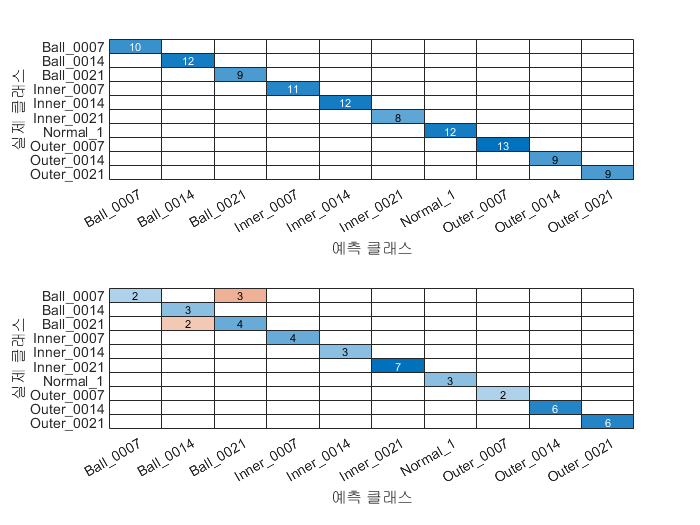

[~, ~, Knn_Test_Loss_Statistical, ~] = ML_KnnTrain(TimeFreq_X_trainData, TimeFreq_Y_trainData, TimeFreq_X_testData, TimeFreq_Y_testData, 3);

#### SVM Train

SVM_CrossValication_Error = 0.0667

SVM_Train_Loss = 0.0381

SVM_Test_Loss = 0.1095

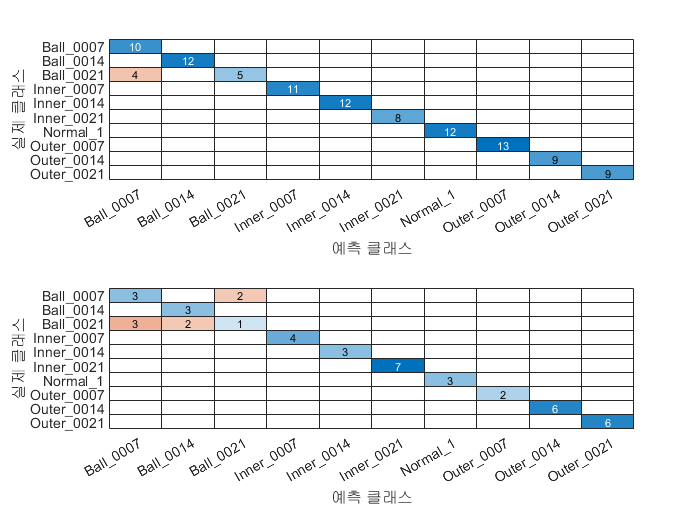

[~, ~, SVM_Test_Loss_Statistical, ~] = ML_SVMTrain(TimeFreq_X_trainData, TimeFreq_Y_trainData, TimeFreq_X_testData, TimeFreq_Y_testData, 3);

#### Decision Tree

Tree_CrossValication_Error = 0.0667

Tree_Train_Loss = 0

Tree_Test_Loss = 0.0286

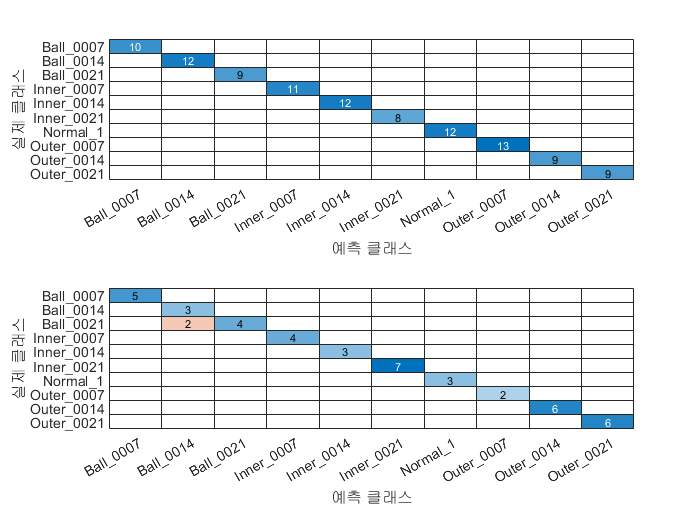

[~, ~, Tree_Test_Loss_Statistical, ~] = ML_TreeTrain(TimeFreq_X_trainData, TimeFreq_Y_trainData, TimeFreq_X_testData, TimeFreq_Y_testData, 3);

### **Envelope Features**

#### KNN

Knn_CrossValication_Error = 0

Knn_Train_Loss = 0

Knn_Test_Loss = 0

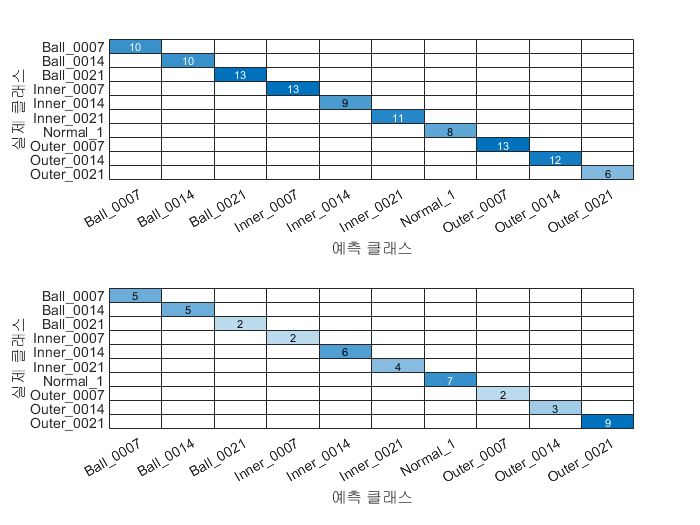

[~, ~, Knn_Test_Loss_Envelope, ~] = ML_KnnTrain(Envelope_X_trainData, Envelope_Y_trainData, Envelope_X_testData, Envelope_Y_testData, 3);

#### SVM Train

SVM_CrossValication_Error = 0

SVM_Train_Loss = 0

SVM_Test_Loss = 0

[~, ~, SVM_Test_Loss_Envelope, ~] = ML_SVMTrain(Envelope_X_trainData, Envelope_Y_trainData, Envelope_X_testData, Envelope_Y_testData, 3);

#### Decision Tree

Tree_CrossValication_Error = 0.0857

Tree_Train_Loss = 0

Tree_Test_Loss = 0.0714

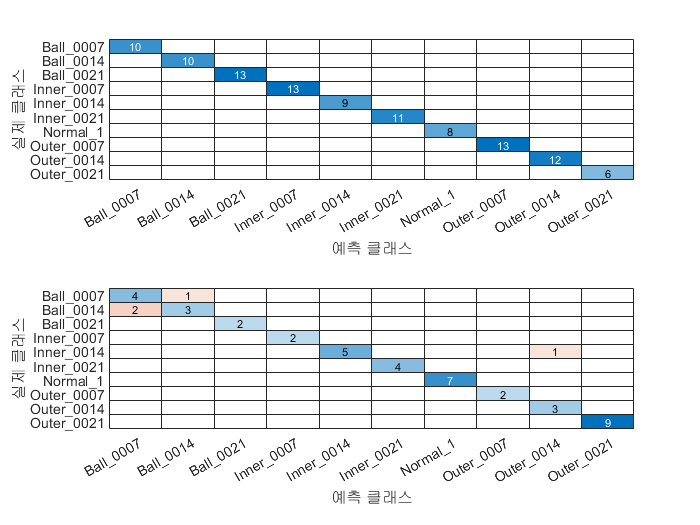

[~, ~, Tree_Test_Loss_Envelope, ~] = ML_TreeTrain(Envelope_X_trainData, Envelope_Y_trainData, Envelope_X_testData, Envelope_Y_testData, 3);

### **Wavelet Features**

#### KNN

Knn_CrossValication_Error = 0

Knn_Train_Loss = 0

Knn_Test_Loss = 0

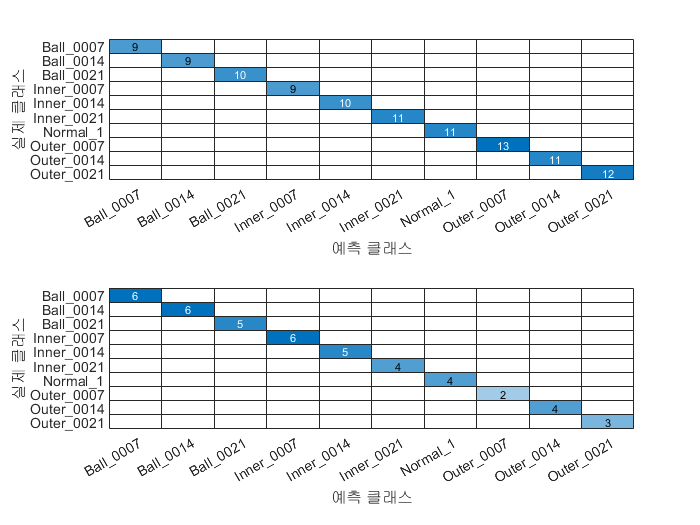

[~, ~, Knn_Test_Loss_Wavelet, ~] = ML_KnnTrain(Wavelet_X_trainData, Wavelet_Y_trainData, Wavelet_X_testData, Wavelet_Y_testData, 3);

#### SVM Train

SVM_CrossValication_Error = 0

SVM_Train_Loss = 0

SVM_Test_Loss = 0

[~, ~, SVM_Test_Loss_Wavelet, ~] = ML_SVMTrain(Wavelet_X_trainData, Wavelet_Y_trainData, Wavelet_X_testData, Wavelet_Y_testData, 3);

#### Decision Tree

Tree_CrossValication_Error = 0.0667

Tree_Train_Loss = 0

Tree_Test_Loss = 0.0381

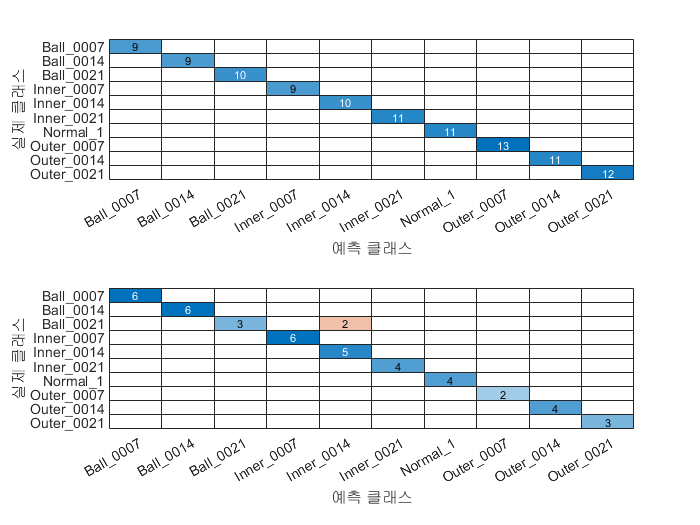

[~, ~, Tree_Test_Loss_Wavelet, ~] = ML_TreeTrain(Wavelet_X_trainData, Wavelet_Y_trainData, Wavelet_X_testData, Wavelet_Y_testData, 3);

### **Global Pool Features**

#### KNN

Knn_CrossValication_Error = 0

Knn_Train_Loss = 0

Knn_Test_Loss = 0

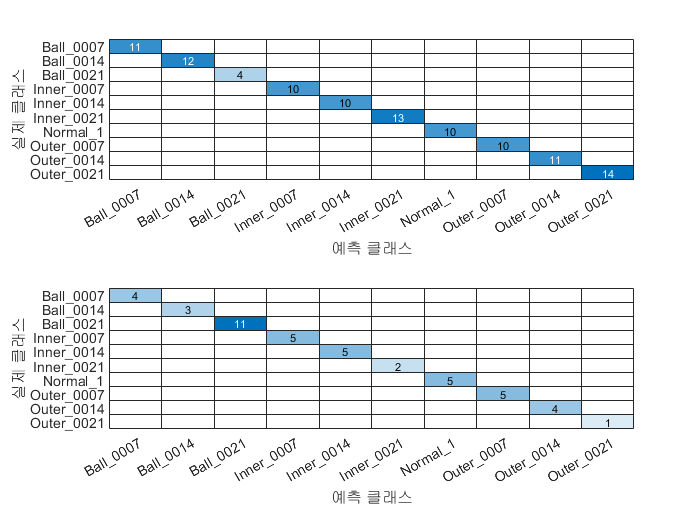

[~, ~, Knn_Test_Loss_Pool, ~] = ML_KnnTrain(Global_X_trainData, Global_Y_trainData, Global_X_testData, Global_Y_testData, 3);

#### SVM Train

SVM_CrossValication_Error = 0

SVM_Train_Loss = 0

SVM_Test_Loss = 0

[~, ~, SVM_Test_Loss_Pool, ~] = ML_SVMTrain(Global_X_trainData, Global_Y_trainData, Global_X_testData, Global_Y_testData, 2);

#### Decision Tree

Tree_CrossValication_Error = 0.0571

Tree_Train_Loss = 0

Tree_Test_Loss = 0.0069

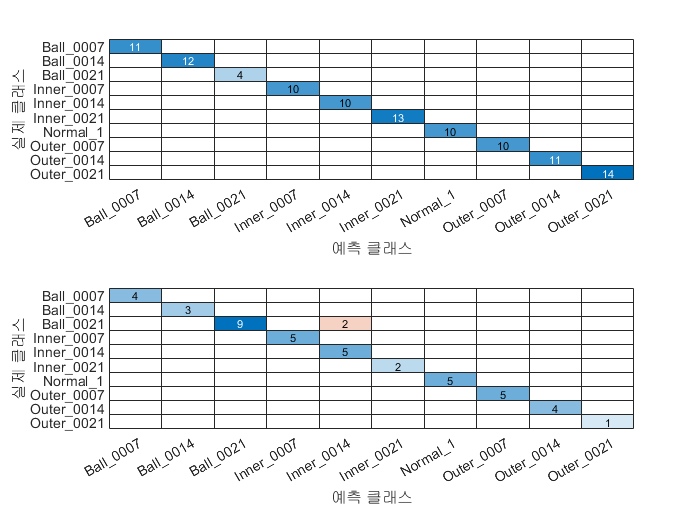

[~, ~, Tree_Test_Loss_Pool, ~] = ML_TreeTrain(Global_X_trainData, Global_Y_trainData, Global_X_testData, Global_Y_testData, 3);

# **5. Data Classification Machine Learning With Feature Reduction/Selection**

## **Sequential Feature Selection**

### Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
Y = height(Global_X_trainData);         % Size of table
cv = cvpartition(Y,'KFold',5)           % k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 105
       NumTestSets: 5
         TrainSize: 84  84  84  84  84
          TestSize: 21  21  21  21  21

### Sequential Feature Selection

% Set up loss function to evaluate the performance
lossfun = 'mincost';

%% For SVM
% fun = @(XT,yT,Xt,yt)loss(fitcecoc(XT,yT),Xt,yt, 'Lossfun', lossfun); 

%% For KNN
k = 1;
fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT, 'NumNeighbors', k, 'Standardize',1), Xt, yt, 'Lossfun', lossfun);

% dir = 'forward';
Global_X_trainData_array      = table2array(Global_X_trainData);
Global_Y_trainData_array      = table2array(Global_Y_trainData);

dir = 'forward';   % direction of selection(forward/backward)
opts = statset('Display','iter');
[inmodel, history] = sequentialfs(fun, Global_X_trainData_array, Global_Y_trainData_array, 'cv', cv, 'options', opts, 'direction', dir)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 23번 열 추가, 기준값 0.00443781
2단계, 102번 열 추가, 기준값 0.00165911
3단계, 124번 열 추가, 기준값 0.000642479
4단계, 113번 열 추가, 기준값 0.000514801
5단계, 2번 열 추가, 기준값 0
최종적으로 포함된 열: 2 23 102 113 124 


inmodel = 1×130 logical 배열
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


history = 다음 필드를 포함한 struct :
      In: [5×130 logical]
    Crit: [0.0044 0.0017 6.4248e-04 5.1480e-04 0]


#### K-fold Loss of All features vs Selected features

% K-fold Loss of all features
knn_mdl    = fitcknn(Global_X_trainData_array, Global_Y_trainData_array);
knn_cvmdl  = crossval(knn_mdl, k=3);   % Performs stratified 10-fold cross-validation
accuracy   = 1 - kfoldLoss(knn_cvmdl)

accuracy = 1

% K-fold Loss of selected features
Global_X_testData_array      = table2array(Global_X_testData);
Global_Y_testData_array      = table2array(Global_Y_testData);

idx_select = find(inmodel);     
Global_X_trainData_array_select  =  Global_X_trainData_array(:, idx_select);
Global_X_testData_array_select   =  Global_X_testData_array(:, idx_select);
Global_X_trainData_select  =  Global_X_trainData(:, idx_select);
Global_X_testData_select   =  Global_X_testData(:, idx_select);

mdl_select         = fitcknn(Global_X_trainData_array_select, Global_Y_trainData_array);
cvmdl_select       = crossval(mdl_select, k=3); 
accuracy_select    = 1 - kfoldLoss(cvmdl_select)

accuracy_select = 1

#### Loss of Test Dataset: All features vs Selected features

% Test Loss of all  features
error = loss(knn_mdl, Global_X_testData_array, Global_Y_testData_array);
accuracy = 1-error

accuracy = 1

% Test Loss of selected  features
error_select = loss(mdl_select, Global_X_testData_array_select,Global_Y_testData_array);
accuracy_select = 1-error_select

accuracy_select = 0.9346

There is no significant difference in accuracy even if the feature is reduced.

As the result of applying the model to Test Dataset was the same as in train data, the direction of reducing the feature is correct for efficient learning.

### **Global Pool Features with **Sequential Feature Selection

#### KNN

Knn_CrossValication_Error = 0

Knn_Train_Loss = 0

Knn_Test_Loss = 0.0654

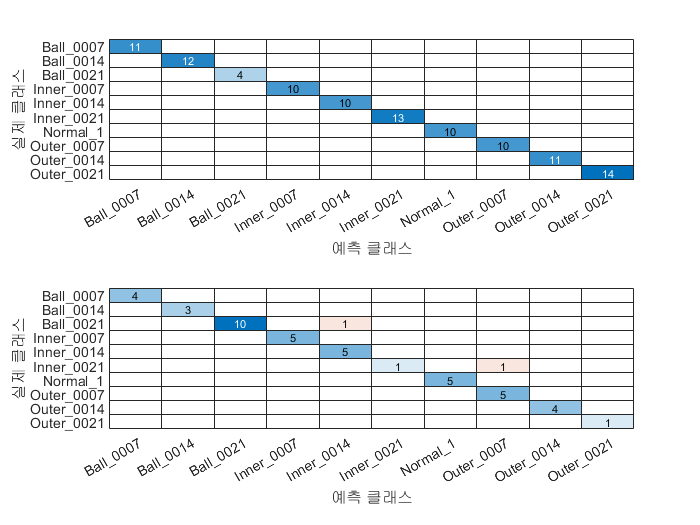

[Knn_CrossValication_Error, Knn_Train_Loss, Knn_Test_Loss_SFS, ~] = ML_KnnTrain(Global_X_trainData_select, Global_Y_trainData, Global_X_testData_select, Global_Y_testData, 3);

#### SVM

SVM_CrossValication_Error = 0.2952

SVM_Train_Loss = 0.1333

SVM_Test_Loss = 0.1299

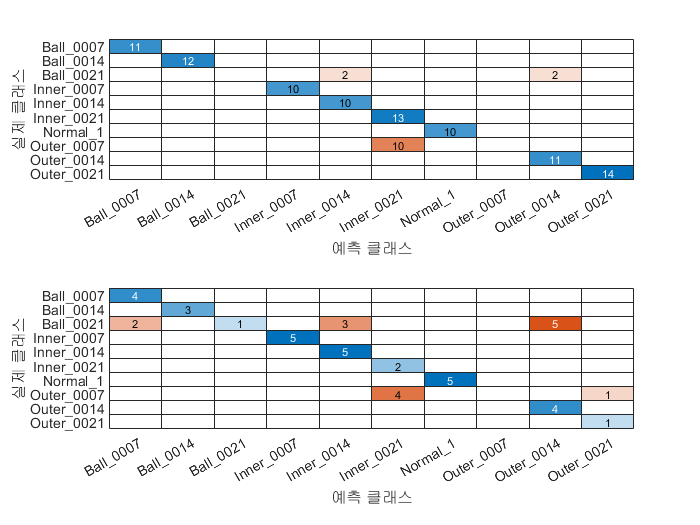

[SVM_CrossValication_Error, SVM_Train_Loss, SVM_Test_Loss_SFS, ~] = ML_SVMTrain(Global_X_trainData_select, Global_Y_trainData, Global_X_testData_select, Global_Y_testData, 3);

#### Decision Tree

Tree_CrossValication_Error = 0.0571

Tree_Train_Loss = 0

Tree_Test_Loss = 0.0069

[Tree_CrossValication_Error, Tree_Train_Loss, Tree_Test_Loss_SFS, ~] = ML_TreeTrain(Global_X_trainData_select, Global_Y_trainData, Global_X_testData_select, Global_Y_testData, 3);

### PCA

### Apply PCA

rng(0)

[coeff, Global_X_trainData_pca, ~, ~, explained, pcaCenter] = pca(Global_X_trainData_array);

#### Select  PCA coefficient with 95% importance

% Returns Explained, the percentage of the total variance explained by each principal component
explained

explained =    37.3139
   14.7996
   13.6130
    8.8745
    6.6827
    5.4970
    2.9768
    2.3309
    1.0134
    0.6640


% The number of components required to account for at least 95% variability. Let's see where the cumulative sum is 95.
explain_standard = .95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

num = 14

As a result of PCA coefficient with 95% importance, it is confirmed that a total of 13 features can be used.

#### Feature Reduction Analysis

coeff = coeff(:,1:num);
Global_X_trainData_pca_select = Global_X_trainData_pca(:,1:num);

[n,p] = size(Global_X_trainData);
meanX = mean(Global_X_trainData_array,1);  


% Xfit: in original coordinate system
Xfit = repmat(meanX,n,1) + Global_X_trainData_pca(:,1:num)*coeff(:,1:num)';

### **Global Pool Features with **Sequential Feature Selection

### KNN

### Train Knn model: PCA data

% Apply multi-class SVM on PCA Global_X_trainData_pca
mdl_pca = fitcknn(Global_X_trainData_pca_select, Global_Y_trainData_array);

### K-fold Loss : PCA

% kfold accuracy of PCA
cvmdl_pca = crossval(mdl_pca, 'Kfold', 3); % Performs stratified 10-fold cross-validation
accuracy_pca_knn = 1 - kfoldLoss(cvmdl_pca);

### Covert Test data to PCA reduced dimension

Convert Test data from originial coordinate to PCA vectors

% cwru_test_pca:  Test data in PCA coefficent vectors
% Convert Test data from originial coordinate to PCA vectors
%  X_pca=(X-meanX)*inv(coeff')

[ntest,~]  = size(Global_X_testData);
mu             = repmat(pcaCenter, ntest, 1);
Global_X_testData_pca  = (Global_X_testData_array - mu)/coeff';

### Confusion Matrix : PCA

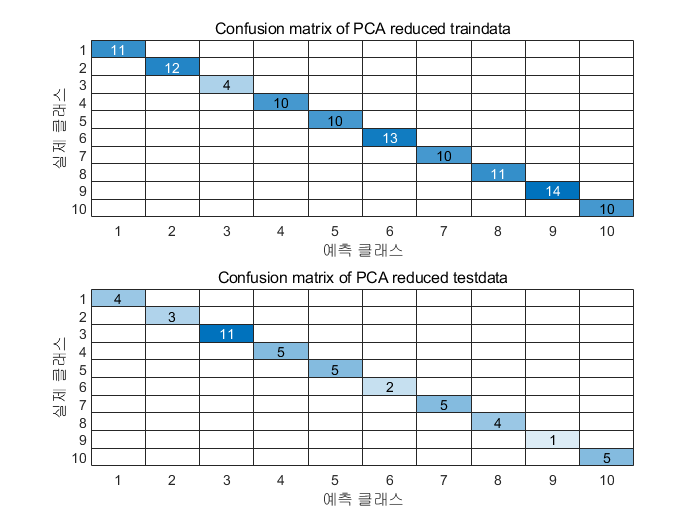

% Calculate Confusion matrix
class_pca_test    = predict(mdl_pca, Global_X_testData_pca);
class_pca_train   = predict(mdl_pca, Global_X_trainData_pca_select);

C_pca_test  = confusionmat(Global_Y_testData_array, class_pca_test);
C_pca_train = confusionmat(Global_Y_trainData_array, class_pca_train);

% Plot Confusion Matrix
figure
subplot(2, 1, 1);   confusionchart(C_pca_train);         title("Confusion matrix of PCA reduced traindata");
subplot(2, 1, 2);   confusionchart(C_pca_test);          title("Confusion matrix of PCA reduced testdata");

accuracy_pca_knn

accuracy_pca_knn = 1

### SVM

### Train Knn model: PCA data

% Apply multi-class SVM on PCA Global_X_trainData_pca
mdl_pca = fitcecoc(Global_X_trainData_pca_select, Global_Y_trainData_array);

### K-fold Loss : PCA

% kfold accuracy of PCA
cvmdl_pca = crossval(mdl_pca, 'Kfold', 3); % Performs stratified 10-fold cross-validation
accuracy_pca_svm = 1 - kfoldLoss(cvmdl_pca);

### Covert Test data to PCA reduced dimension

Convert Test data from originial coordinate to PCA vectors

% cwru_test_pca:  Test data in PCA coefficent vectors
% Convert Test data from originial coordinate to PCA vectors
%  X_pca=(X-meanX)*inv(coeff')

[ntest,~]  = size(Global_X_testData);
mu             = repmat(pcaCenter, ntest, 1);
Global_X_testData_pca  = (Global_X_testData_array - mu)/coeff';

### Confusion Matrix : PCA

% Calculate Confusion matrix
class_pca_test    = predict(mdl_pca, Global_X_testData_pca);
class_pca_train   = predict(mdl_pca, Global_X_trainData_pca_select);

C_pca_test  = confusionmat(Global_Y_testData_array, class_pca_test);
C_pca_train = confusionmat(Global_Y_trainData_array, class_pca_train);

% Plot Confusion Matrix
figure
subplot(2, 1, 1);   confusionchart(C_pca_train);         title("Confusion matrix of PCA reduced traindata");
subplot(2, 1, 2);   confusionchart(C_pca_test);          title("Confusion matrix of PCA reduced testdata");

accuracy_pca_svm

accuracy_pca_svm = 1

### Decision Tree

### Train Knn model: PCA data

% Apply multi-class SVM on PCA Global_X_trainData_pca
mdl_pca = fitctree(Global_X_trainData_pca_select, Global_Y_trainData_array);

### K-fold Loss : PCA

% kfold accuracy of PCA
cvmdl_pca = crossval(mdl_pca, 'Kfold', 3); % Performs stratified 10-fold cross-validation
accuracy_pca_tree = 1 - kfoldLoss(cvmdl_pca);

### Covert Test data to PCA reduced dimension

Convert Test data from originial coordinate to PCA vectors

% cwru_test_pca:  Test data in PCA coefficent vectors
% Convert Test data from originial coordinate to PCA vectors
%  X_pca=(X-meanX)*inv(coeff')

[ntest,ptest]  = size(Global_X_testData);
mu             = repmat(pcaCenter, ntest, 1);
Global_X_testData_pca  = (Global_X_testData_array - mu)/coeff';

### Confusion Matrix : PCA

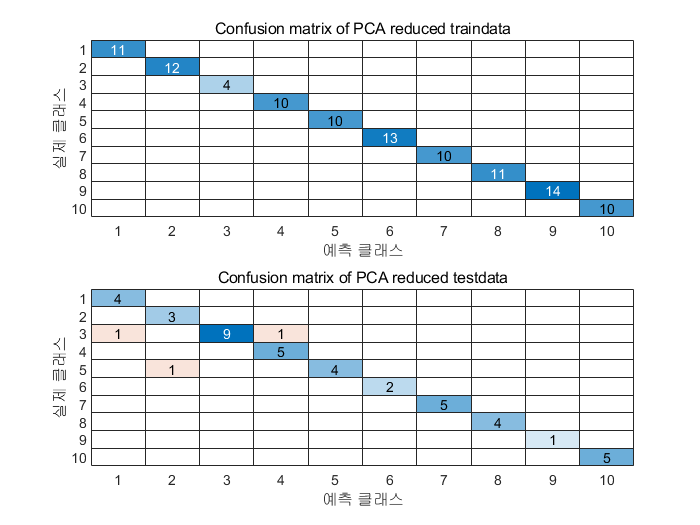

% Calculate Confusion matrix
class_pca_test    = predict(mdl_pca, Global_X_testData_pca);
class_pca_train   = predict(mdl_pca, Global_X_trainData_pca_select);

C_pca_test  = confusionmat(Global_Y_testData_array, class_pca_test);
C_pca_train = confusionmat(Global_Y_trainData_array, class_pca_train);

% Plot Confusion Matrix
figure
subplot(2, 1, 1);   confusionchart(C_pca_train);         title("Confusion matrix of PCA reduced traindata");
subplot(2, 1, 2);   confusionchart(C_pca_test);          title("Confusion matrix of PCA reduced testdata");

accuracy_pca_tree

accuracy_pca_tree = 0.8857

## Evaluation

Accuracy_Knn_Statistical  = (1 - Knn_Test_Loss_Statistical)*100;
Accuracy_SVM_Statistical  = (1 - SVM_Test_Loss_Statistical)*100;
Accuracy_Tree_Statistical = (1 - Tree_Test_Loss_Statistical)*100;
Accuracy_Statistical      = [Accuracy_Knn_Statistical, Accuracy_SVM_Statistical, Accuracy_Tree_Statistical];

Accuracy_Knn_Wavelet   = (1 - Knn_Test_Loss_Wavelet)*100;
Accuracy_SVM_Wavelet   = (1 - SVM_Test_Loss_Wavelet)*100;
Accuracy_Tree_Wavelet  = (1 - Tree_Test_Loss_Wavelet)*100;
Accuracy_Wavelet       = [Accuracy_Knn_Wavelet, Accuracy_SVM_Wavelet, Accuracy_Tree_Wavelet];

Accuracy_Knn_Envelope  = (1 - Knn_Test_Loss_Envelope)*100;
Accuracy_SVM_Envelope  = (1 - SVM_Test_Loss_Envelope)*100;
Accuracy_Tree_Envelope = (1 - Tree_Test_Loss_Envelope)*100;
Accuracy_Envelope      = [Accuracy_Knn_Envelope, Accuracy_SVM_Envelope, Accuracy_Tree_Envelope];

Accuracy_Knn_Pool      = (1 - Knn_Test_Loss_Pool)*100;
Accuracy_SVM_Pool      = (1 - SVM_Test_Loss_Pool)*100;
Accuracy_Tree_Pool     = (1 - Tree_Test_Loss_Pool)*100;
Accuracy_Pool          = [Accuracy_Knn_Pool, Accuracy_SVM_Pool, Accuracy_Tree_Pool];

Accuracy_Array = [Accuracy_Statistical;Accuracy_Wavelet;Accuracy_Envelope;Accuracy_Pool];

RowIndex    = ['       Statistical       ' ; '     Wavelet Package     ' ; 'Complex Envelope Spectrum' ; '      Complete Pool      '];
ColumnIndex = ['     1-NN    ' ; '     SVM     ' ; 'Decision Tree'];

Accuracy_Table = array2table(Accuracy_Array,'RowNames',string(RowIndex),'VariableNames',string(ColumnIndex) )

Accuracy_Table = 4×3 table
                                      1-NN             SVM         Decision Tree
                                 _____________    _____________    _____________

    Statistical                     91.429           89.048           97.143    
    Wavelet Package                    100              100            96.19    
    Complex Envelope Spectrum          100              100           92.857    
    Complete Pool                      100              100           99.307    


Accuracy_Knn_Test_Loss_SFS   = (1 - Knn_Test_Loss_SFS)*100;
Accuracy_SVM_Test_Loss_SFS   = (1 - SVM_Test_Loss_SFS)*100;
Accuracy_Tree_Test_Loss_SFS  = (1 - Tree_Test_Loss_SFS)*100;

SFS_PCA_Accuracy_Array = [Accuracy_Knn_Test_Loss_SFS ; accuracy_pca_knn*100 ; Accuracy_SVM_Test_Loss_SFS ; accuracy_pca_svm*100 ; Accuracy_Tree_Test_Loss_SFS ; accuracy_pca_tree*100];
RowIndex    = ['KNN  SFS' ; 'KNN  PCA' ; 'SVM  SFS' ; 'SVM  PCA' ; 'Tree SFS' ; 'Tree PCA'];
ColumnIndex = 'Accuracy';

SFS_PCA_Accuracy_Table = array2table(SFS_PCA_Accuracy_Array,'RowNames',string(RowIndex),'VariableNames',string(ColumnIndex) )

SFS_PCA_Accuracy_Table = 6×1 table
                Accuracy
                ________

    KNN  SFS     93.463 
    KNN  PCA        100 
    SVM  SFS     87.013 
    SVM  PCA        100 
    Tree SFS     99.307 
    Tree PCA     88.571 


# Conclusion & Discussion

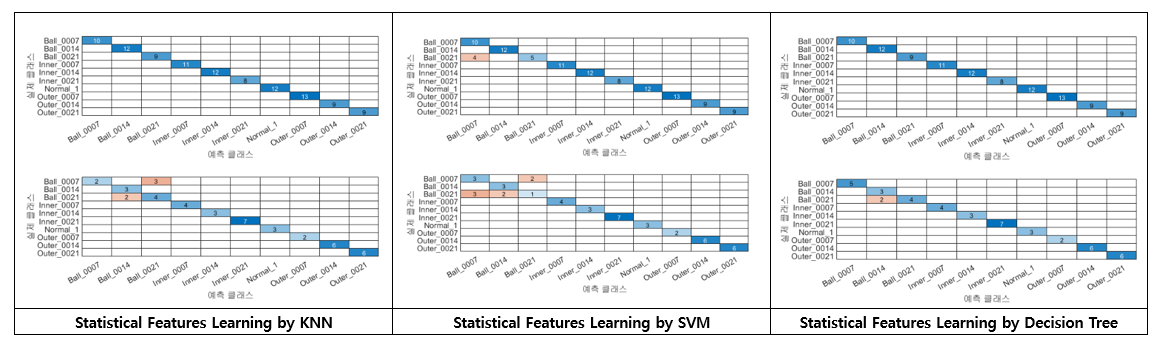

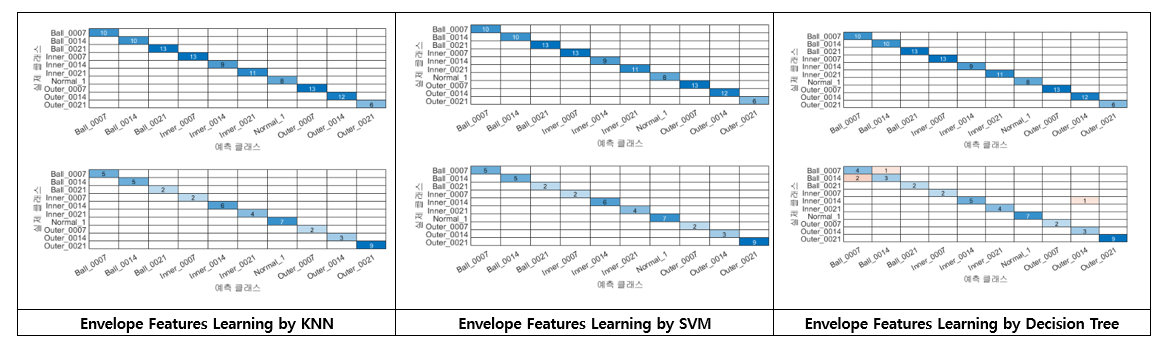

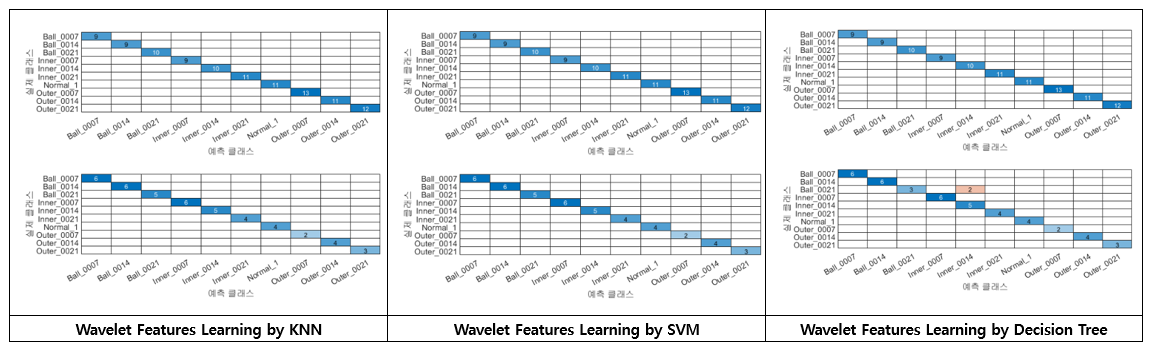

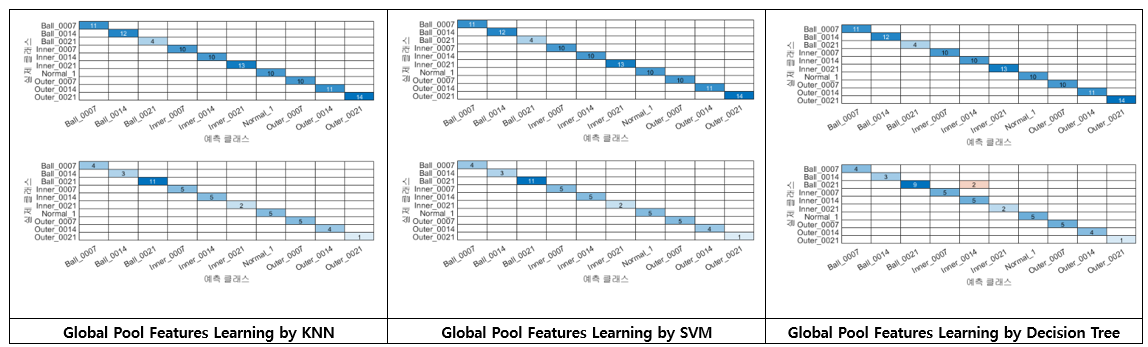

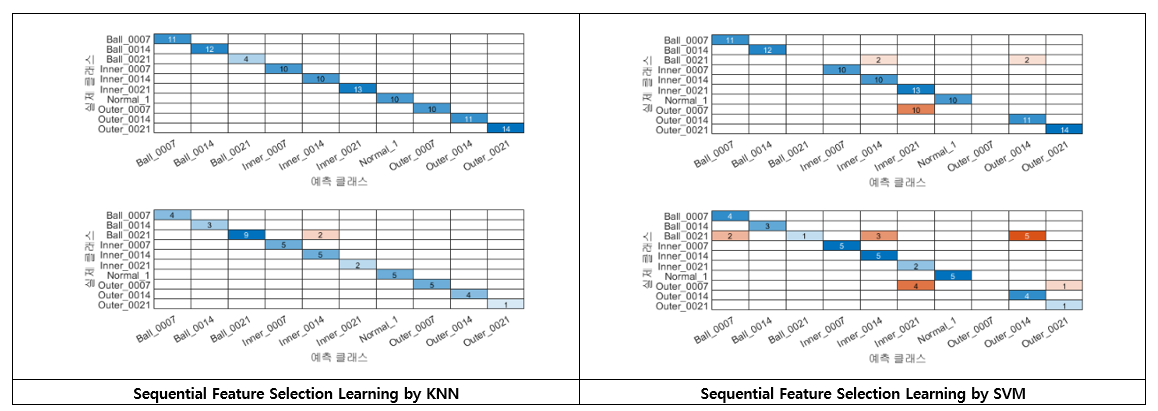

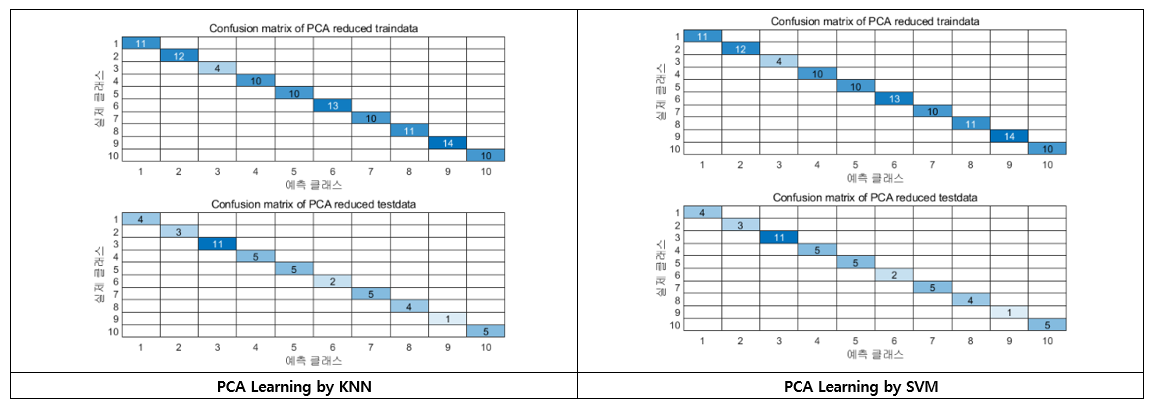

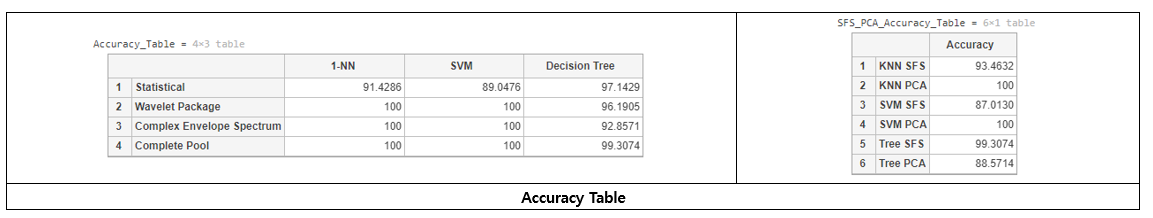

Looking at the Accuracy Table above, it can be seen that there is a difference from the accuracy value presented in the paper.

In this paper, there was no detailed description of the data pre-processing, such as data normalization, train data and test data segmentation, and there was no description of the parameter options specified in the model learning process. Therefore, it is judged that such a result was obtained as a result of differences in data pre-processing methods and differences in parameter options designated in the model learning process.

However, only the values are different, but overall, I think the same conclusion as the paper can be reached.

- In the case of Statistical Feature, the accuracy was somewhat low regardless of which learning model was selected.

- In the case of Complete Global Pool, no matter which learning model we choose, the accuracy was large. It is judged that the accuracy increases as the number of features to be considered increases.

- Overall, comparing the accuracy according to the type of feature is as follows. Pool > Wavelet > Envelope > Statistical

- Overall, comparing the accuracy according to the type of model is as follows. Knn ≒ SVM > Decision Tree

- In Sequential Feature Selection, it can be seen that the accuracy decreases significantly when SVM is applied.

- When PCA was applied, the accuracy was relatively good in all learning models. Therefore, in the CWRU Dataset, a direction in which PCA is applied in the feature reduction process seems to be desirable.